**Homework Assignment 1**

SZF & EA, 2023

PQ. 1

clear all; close all; clc

test_results = struct()

test_results = struct with no fields.


test_data = struct()

test_data = struct with no fields.



A = eye(3);
myTest(:,:,1) = A;

B = elemRot('x',90);
myTest(:,:,2) = B;

C = elemRot('y',90);
myTest(:,:,3) = C;

D = elemRot('z',90);
myTest(:,:,4) = D;

E = B*C;
myTest(:,:,5) = E;

F = B*C*D;
myTest(:,:,6) = F;

for idx=1:length(myTest(1,1,:))
    test_results(idx).AA = rot2AA(myTest(:,:,idx));
    test_results(:,idx).Quat = rot2Quat(myTest(:,:,idx));
    test_results(idx).ZYZ = rot2ZYZ(myTest(:,:,idx));
    test_results(idx).ZYX = rot2ZYX(myTest(:,:,idx));
    
    % Generate data for testing question 2 functions with matlab functions
    % This is to provide valid quaternion and axis angle representation data points
    test_data(idx,:).Quat = rotm2quat(myTest(:,:,idx));
    test_data(idx,:).AA = rotm2axang(myTest(:,:,idx));

end

To access each of the test results, use the appropriate field name to access the desired element of the struct. For example, to access the axis angle representation of the second test case:

myAxis02 = test_results(2).AA.Axis

myAxis02 =      1
     0
     0


myAngle02 = test_results(2).AA.Angle

myAngle02 = 1.5708

PQ. 2

% CODE GOES HERE
% Can use results from test above for input axis angle and quaternion matrices

Q2_Test = struct();

for idx = 1:length(myTest(1,1,:))
    Q2_Test(idx).QtoR = quaternian_to_rotation(test_data(idx,:).Quat');
    aa2r_data = test_data(idx,:).AA; 
    w = aa2r_data(1:3);
    theta = aa2r_data(4); 
    Q2_Test(idx).AAtoR = axisangle_to_rotation(w',theta)    

end

Q2_Test = struct with fields:
     QtoR: [3×3 double]
    AAtoR: [3×3 double]


Q2_Test = 1×2 struct array with fields:
    QtoR
    AAtoR


Q2_Test = 1×3 struct array with fields:
    QtoR
    AAtoR


Q2_Test = 1×4 struct array with fields:
    QtoR
    AAtoR


Q2_Test = 1×5 struct array with fields:
    QtoR
    AAtoR


Q2_Test = 1×6 struct array with fields:
    QtoR
    AAtoR


PQ. 3

q = [0,2,0];
s = [0,0,1];
h = 2;

Screw01 = Screw(q,s,h)

Screw01 =   Screw with properties:

            q: [0 2 0]
            s: [0 0 1]
            h: 2
    theta_dot: 1



theta = pi;

T0 = [1 0 0 2;
      0 1 0 0;
      0 0 1 0;
      0 0 0 1];

T1 = zeros(4,4,4);

for a = 1:4
    T_Screw = Screw01.getScrewExp(a*theta/4)
    
    T1(:,:,a) = T_Screw*T0
end

v =      2     0     2


T_Screw =     0.7071   -0.7071         0    1.5708
    0.7071    0.7071         0    0.8990
         0         0    1.0000    1.5708
         0         0         0    1.0000


T1 = T1(:,:,1) =

    0.7071   -0.7071         0    2.9850
    0.7071    0.7071         0    2.3132
         0         0    1.0000    1.5708
         0         0         0    1.0000


T1(:,:,2) =

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


T1(:,:,3) =

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


T1(:,:,4) =

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


v =      2     0     2


T_Screw =     0.0000   -1.0000         0    3.1416
    1.0000    0.0000         0    4.2832
         0         0    1.0000    3.1416
         0         0         0    1.0000


T1 = T1(:,:,1) =

    0.7071   -0.7071         0    2.9850
    0.7071    0.7071         0    2.3132
         0         0    1.0000    1.5708
         0         0         0    1.0000


T1(:,:,2) =

    0.0000   -1.0000         0    3.1416
    1.0000    0.0000         0    6.2832
         0         0    1.0000    3.1416
         0         0         0    1.0000


T1(:,:,3) =

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


T1(:,:,4) =

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


v =      2     0     2


T_Screw =    -0.7071   -0.7071         0    4.7124
    0.7071   -0.7071         0   10.0106
         0         0    1.0000    4.7124
         0         0         0    1.0000


T1 = T1(:,:,1) =

    0.7071   -0.7071         0    2.9850
    0.7071    0.7071         0    2.3132
         0         0    1.0000    1.5708
         0         0         0    1.0000


T1(:,:,2) =

    0.0000   -1.0000         0    3.1416
    1.0000    0.0000         0    6.2832
         0         0    1.0000    3.1416
         0         0         0    1.0000


T1(:,:,3) =

   -0.7071   -0.7071         0    3.2982
    0.7071   -0.7071         0   11.4248
         0         0    1.0000    4.7124
         0         0         0    1.0000


T1(:,:,4) =

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


v =      2     0     2


T_Screw =    -1.0000   -0.0000         0    6.2832
    0.0000   -1.0000         0   16.5664
         0         0    1.0000    6.2832
         0         0         0    1.0000


T1 = T1(:,:,1) =

    0.7071   -0.7071         0    2.9850
    0.7071    0.7071         0    2.3132
         0         0    1.0000    1.5708
         0         0         0    1.0000


T1(:,:,2) =

    0.0000   -1.0000         0    3.1416
    1.0000    0.0000         0    6.2832
         0         0    1.0000    3.1416
         0         0         0    1.0000


T1(:,:,3) =

   -0.7071   -0.7071         0    3.2982
    0.7071   -0.7071         0   11.4248
         0         0    1.0000    4.7124
         0         0         0    1.0000


T1(:,:,4) =

   -1.0000   -0.0000         0    4.2832
    0.0000   -1.0000         0   16.5664
         0         0    1.0000    6.2832
         0         0         0    1.0000



[S_o,phi] = screwMatLog(T1);
s_hat = S_o(1:3);
h = S_o(1:3)'*S_o(4:6);
syms q1 q2 q3
q = [q1,q2,q3];
LHS = S_o(4:6)- h*s_hat;
RHS = cross(-s_hat,q);
eqs = [RHS(1) == LHS(1);RHS(2) == LHS(2);RHS(3) == LHS(3)];

% To find a solution for q, set q3 = 0
sol = solve(eqs(1:2),[q1;q2]);
q1 = double(sol.q1);
q2 = double(sol.q2);
q3 = 0;

q = [q1,q2,q3];


Plotting for PQ. 3

figure(1)
origin = T0; 

plot3( [0;5;0;0;0;0], [0;0;0;5;0;0], [0;0;0;0;0;5],'k'); hold on

plot3( [origin(1,4);origin(1,4)+origin(1,1)], [origin(2,4);origin(2,4)+origin(1,2)], [origin(3,4);origin(3,4)+origin(1,3)], 'r');
plot3( [origin(1,4);origin(1,4)+origin(2,1)], [origin(2,4);origin(2,4)+origin(2,2)], [origin(3,4);origin(3,4)+origin(2,3)], 'b')
plot3( [origin(1,4);origin(1,4)+origin(3,1)], [origin(2,4);origin(2,4)+origin(3,2)], [origin(3,4);origin(3,4)+origin(3,3)], 'g')

for idx = 1:length(T1(1,1,:))
    
    intermed_T = T1(:,:,idx)

    plot3( [intermed_T(1,4);intermed_T(1,4)+intermed_T(1,1)], [intermed_T(2,4);intermed_T(2,4)+intermed_T(1,2)], [intermed_T(3,4);intermed_T(3,4)+intermed_T(1,3)], 'r');
    plot3( [intermed_T(1,4);intermed_T(1,4)+intermed_T(2,1)], [intermed_T(2,4);intermed_T(2,4)+intermed_T(2,2)], [intermed_T(3,4);intermed_T(3,4)+intermed_T(2,3)], 'b')
    plot3( [intermed_T(1,4);intermed_T(1,4)+intermed_T(3,1)], [intermed_T(2,4);intermed_T(2,4)+intermed_T(3,2)], [intermed_T(3,4);intermed_T(3,4)+intermed_T(3,3)], 'g')
end

intermed_T =     0.7071   -0.7071         0    2.9850
    0.7071    0.7071         0    2.3132
         0         0    1.0000    1.5708
         0         0         0    1.0000


intermed_T =     0.0000   -1.0000         0    3.1416
    1.0000    0.0000         0    6.2832
         0         0    1.0000    3.1416
         0         0         0    1.0000


intermed_T =    -0.7071   -0.7071         0    3.2982
    0.7071   -0.7071         0   11.4248
         0         0    1.0000    4.7124
         0         0         0    1.0000


intermed_T =    -1.0000   -0.0000         0    4.2832
    0.0000   -1.0000         0   16.5664
         0         0    1.0000    6.2832
         0         0         0    1.0000


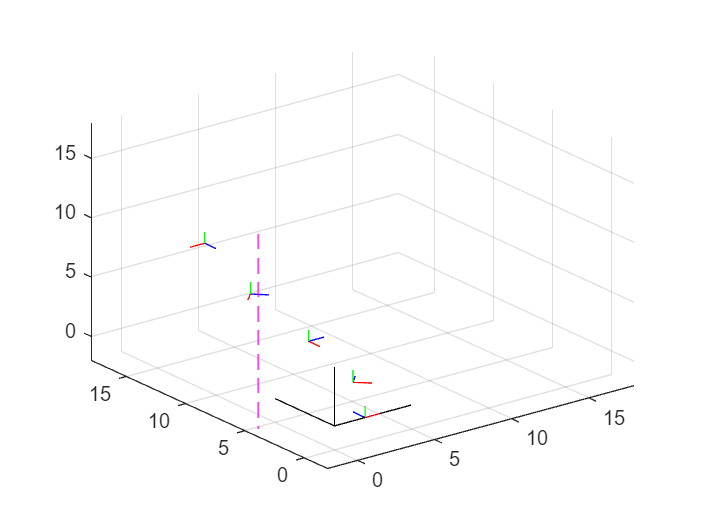


plot3([q1;q1],[q2,q2],[-3,15],'m--')

grid on
axis([-2 18    -2 18    -2 18])